# **Visualisation and map manipulation in Cell Designer (PART 2)**

## Authors: 

## Jennifer Modamio, Anna Danielsdottir, Systems Biochemistry group, University of Luxembourg.

## Nicolas Sompairac, Bioinformatics and Computational Systems Biology of Cancer, Institut Curie.

## **Reviewer(s): Ronan Fleming, Inna Kuperstein and Andrei Zinovyev. **

**(before starting this tutorial, please do PART 1)***

## **4. Erase coloring of the map**

In order to better visualize small changes it might be necessary to unify the rest of colours in the map. The function `unifyMetabolicMapCD` changes all nodes colour to white and reactions colour to light grey and width to 1 (usually set as default).

mapGlyUnified = unifyMetabolicMapCD(mapGly);
transformMap2XML(xmlGly, mapGlyUnified, 'mapGlyUnified.xml');

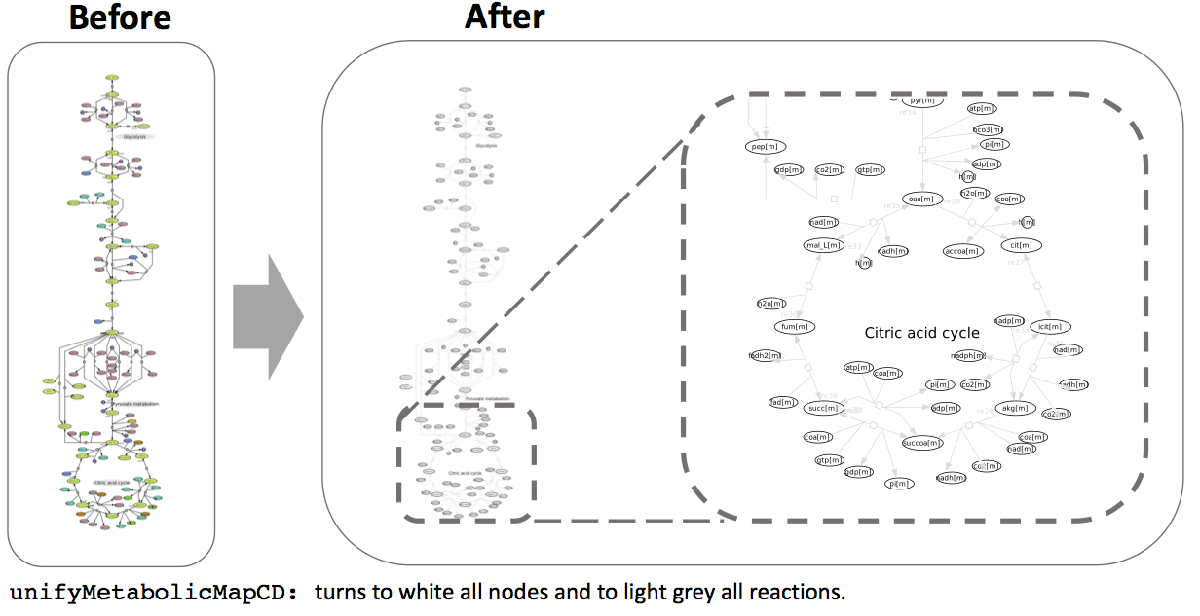

## **5. Change reactions and specific nodes color and width **

The combination of previously mentioned functions can be summarise by the function `modifyReactionsMetabolites.` This function colours a list of reactions and specific metabolites linked to these reactions. In this example, reactions containing "mitochondrial ATP and ADP" will be coloured in Dodger-blue and have a width of 10. Furthremore, the two described metabolites will be also coloured. 

mapGlyATPADPRxns = modifyReactionsMetabolites(mapGlyUnified, ...
    rxnsATPADP , {'atp[m]';'adp[m]'}, 'DODGERBLUE', 10);
transformMap2XML(xmlGly, ...
    mapGlyATPADPRxns, 'mapGlyATPADPRxnsAllColoured.xml');


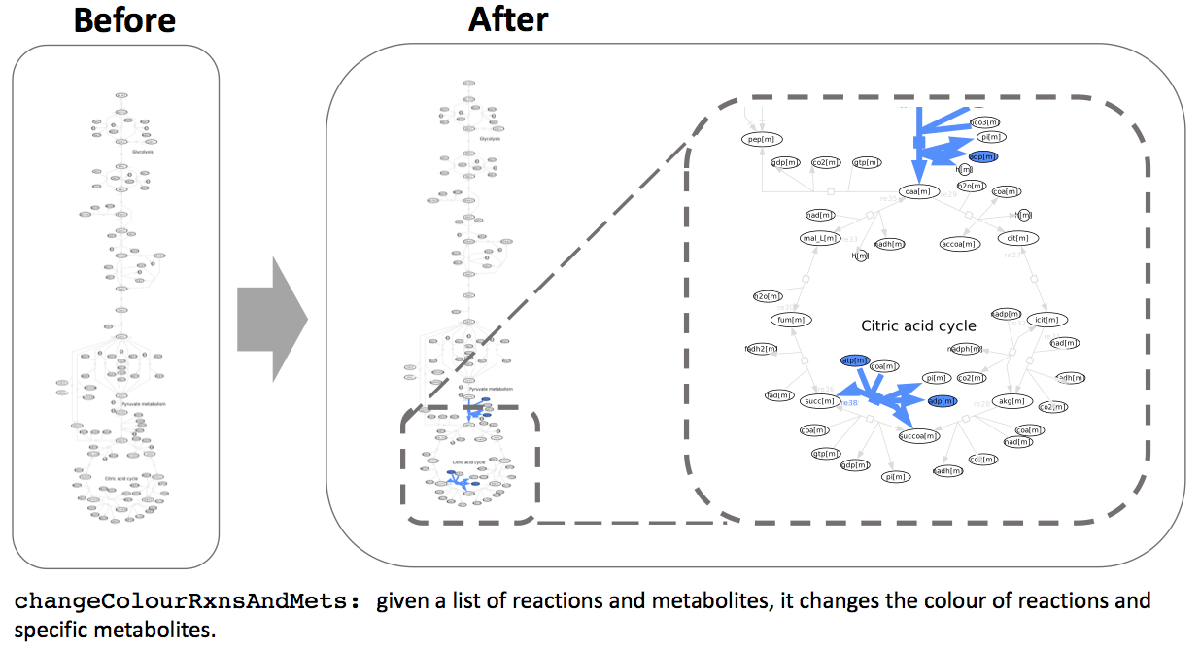

## **6. Colour subsystems**

The function `colorSubsystemCD` colours all reactions associated to a specific subsystem in the model (a subsystem is to be understood as a metabolic pathway). Furthermore changes in the width are also possible. Here three subsystems are differentially coloured: Glycolysis, TCA and Pyruvate metabolism.

mapSubSystems = colorSubsystemCD(mapGly, ...
    model, 'Citric acid cycle', 'HOTPINK', 10);
mapSubSystems = colorSubsystemCD(mapSubSystems, ...
    model, 'Pyruvate metabolism', 'DARKMAGENTA' , 10);
mapSubSystems = colorSubsystemCD(mapSubSystems, ...
    model, 'Glycolysis/gluconeogenesis', 'SPRINGGREEN', 10);
transformMap2XML(xmlGly, ...
    mapSubSystems,'mapGlySubsystemsColoured.xml');

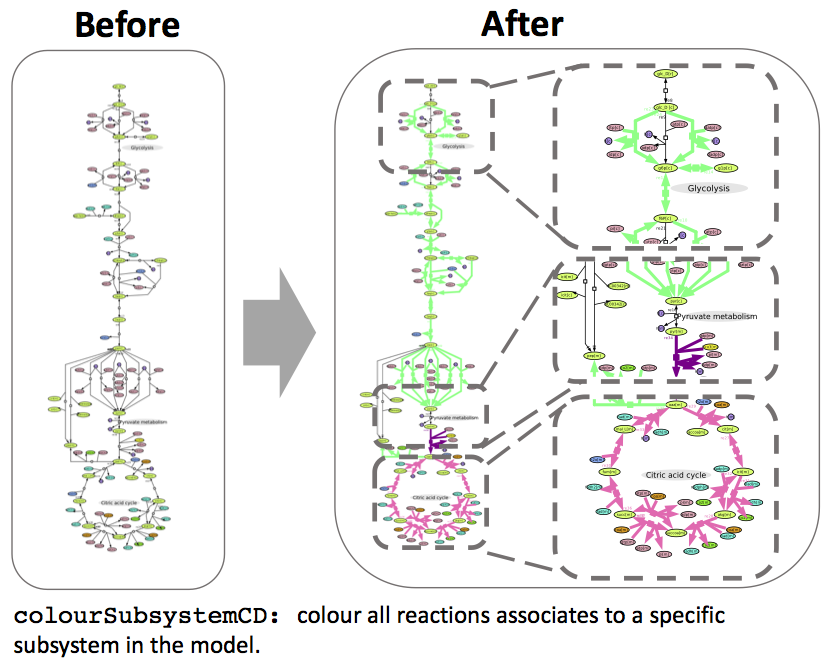

## **7. Colour reactions associated to specific genes**

The function `colorRxnsFromGenes` colours metabolic reactions linked to a gene based on a list of Entrez references. A list of mitochondria-associated genes was obtained from mitocarta 2.0 [5]. Based on this list of genes, we would like to know how many reactions in our metabolic map are associated to these genes. 

load('mitocartaHumanGenes.mat')
mapMitocarta = colorRxnsFromGenes(mapMitoMetab, model, ...
    mitocartaHumanGenes, 'CRIMSON', 10);

Undefined function or variable 'mapMitoMetab'.


transformMap2XML(xmlMitoMetab, ...
    mapMitocarta, 'mapMitocartaHumanGenes.xml');

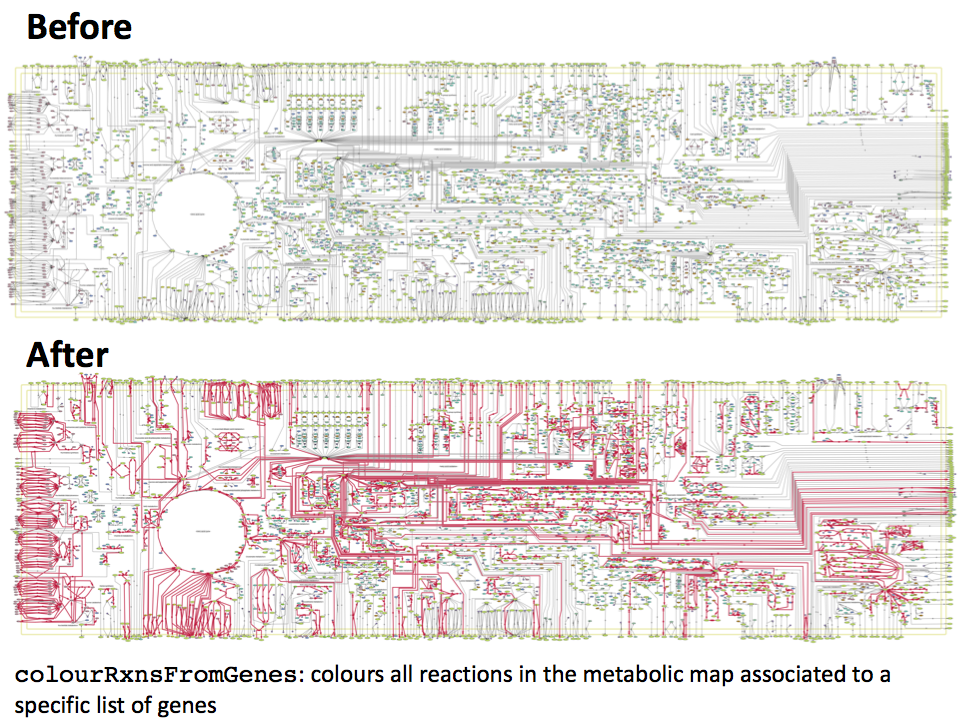

## 8. Change and visualize reaction types

One of the characteristics of CD, is the possibility to represent different types of reactions depending on the interaction that needs to be ilustrated. As for example, the common reaction type is named "STATE TRANSITION" (check `map.rxnsType`).  Reactions can be modified manually; however it can also be done automatically with the function `changeRxnType`. In the next example, we identify transport reactions in Recon2 model, and we change them to "TRANSPORT" type in the map. 

First, we obtain reactions associated to all transport subsystems in Recon2 model: 

transportMitochondria = ismember([model.subSystems{:}]', 'Transport');
index=find(transportMitochondria);
transportReactions = model.rxns(index,1);

Afterwards, we use this list of reactions to change the reaction type in the map. As a result, all "transport" reactions in the model will be converted to "transport" type in the map.

mitoMapTransport = changeRxnType(mapMitoMetab, transportReactions, 'TRANSPORT');

Furthermore, we would like to visualize these "transport" reactions: 

mitoMapTransportColoured = colorRxnType(mitoMapTransport, ...
    'TRANSPORT', 'DARKORCHID', 10);
transformMap2XML(xmlMitoMetab, mitoMapTransportColoured, ...
    'mapMitocartaTransportColoured.xml');

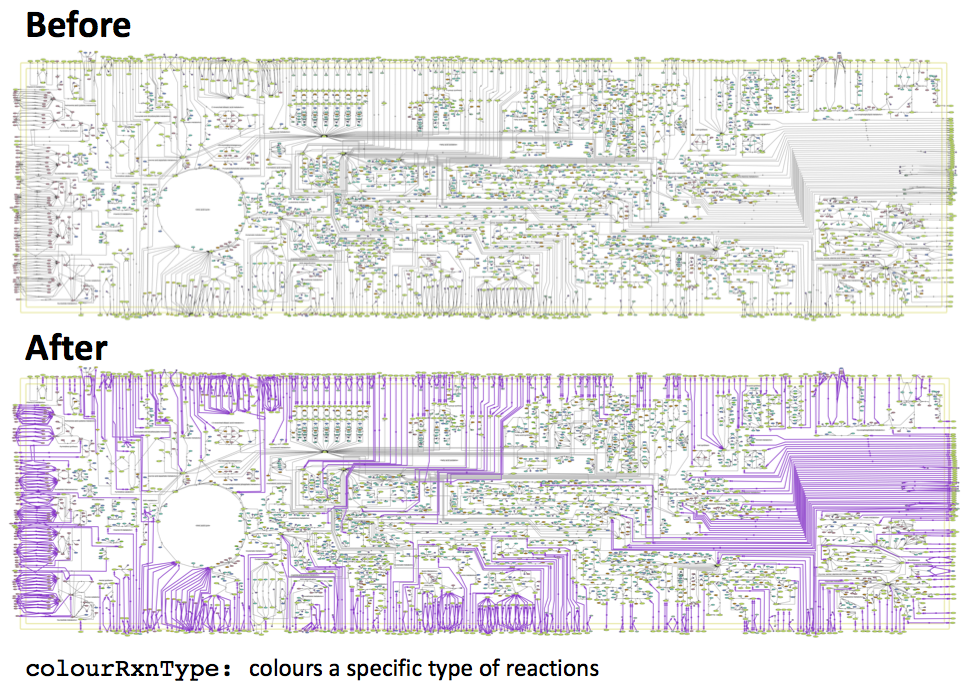

## 9. Changing the node sizes in CellDesigner

Molecule sizes can be modified by changing their height and width with the function `changeNodesArea` by giving a list of molecule names. Previously, we visualized mitochondrial ATP and ADP. Here we would like to modify their size in the map. The measures given are: heigth 100 and width 80.

 mapNodesArea = changeNodesArea(mapGly, {'atp[m]'; 'adp[m]'}, 100, 80);
 transformMap2XML(xmlGly, mapNodesArea, 'mapNodesArea.xml');

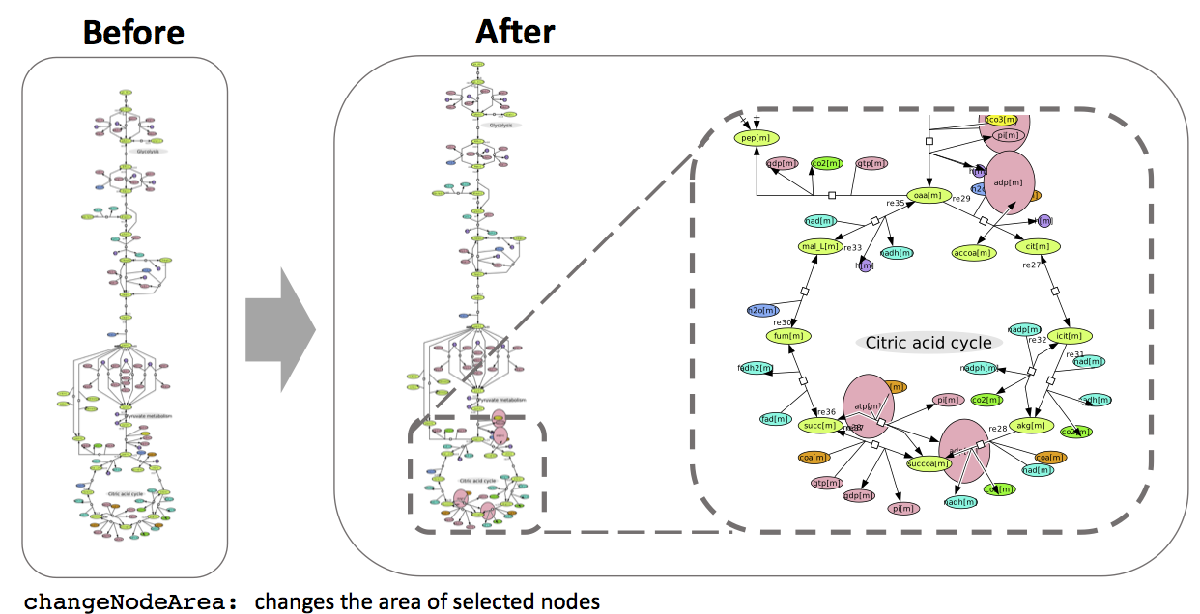

***NOTE! ****Size of metabolites can be automatically modified. However coordinates of metabolites in the map will remain the same. Due to this, changes in size might lead to overlapping between entities.*

## TROUBLESHOOTING

In order to come back to the default map, two functions revert the changes saved in the map. `defaultColourCD` reverts the changes in reactions width and colour (revert all reactions to black and width 1). Furthremore,  `defaultLookMap` reverts to default reactions colour and width (black and 1) and metabolites colour and size (a specific colour is given depending on metabolite type, moreover the size is also given depending on metabolite relevance). 

mapDefault = defaultColorCD(mapGly);
mapDefaultAll = defaultLookMap(mapGly);

## Functions mimicking COBRA functions for model manipulation

## **1. Obtain logical matrices**

Based on the COBRA model structure of the S matrix, similar matrices can be created based on the map. Three logical matrices will be added to the map structure:

- sID: Logical matrix with rows=speciesID and columns=reactionsID

- sAlias: Logical matrix with rows=speciesAlias and columns=reactionsID

- idAlias: Logical matrix with rows=speciesID and columns=speciesAlias

These matrices will be added to the map structure by the function `getMapMatrices`.

mapGlyCorrected = getMapMatrices(mapGlyCorrected);

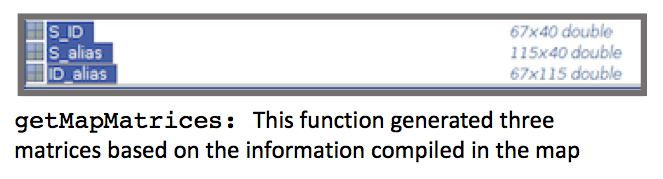

***NOTE!**** To use these matrices with COBRA, this function should be used with Metabolic only maps. An error will occur if used with PPI maps!*

## **2. Research of indexes in the map structure**

Basic functions were created to simplify the manipulation of maps. 

The function `findRxnsPerTypeInMap` gives a list of desired reactions based on the reaction type (2nd colum), and the index for those reactions in `map.rxnName` (1st colum). 

transportReactionsIndexList = findRxnsPerTypeInMap(mapGlyCorrected, 'TRANSPORT');

The function `findMetsInMap` finds the IDs of specific metabolites in `map.specName` given a list of metabolites.  

ATPADPIndexList = findMetsInMap(mapGlyCorrected, ...
    {'atp[c]', 'adp[c]', 'atp[m]', 'adp[m]'});

The function `findRxnsInMap` finds the IDs of specific reactions in `map.rxnName` given a list of reactions.

rxnOfInterestIndexList = findRxnsInMap(mapGlyCorrected, ...
    {'FBP', 'FBA', 'GAPD', 'PFK', 'ENO'});

The function `findMetsFromCompartInMap` finds all metabolites in the map associated to a specific compartment by looking at the composition of metabolite names (example: mitochondrial atp = atp**[m]**). 

[mitochondrialMetsNameList,mitochondrialMetsIndexList] = ...
    findMetsFromCompartInMap(mapGlyCorrected, '[m]');

The function `findRxnsFromCompartInMap` finds all reactions in the map associated to a specific compartment by looking at the composition of metabolite names. 

mitochondrialRxnsIndexList = ...
    findRxnsFromCompartInMap(mapGlyCorrected, '[m]');

# Visualisation of Metabolic and PPI networks

Some of the aforementioned functions were addapted to be used in metabolic and PPi maps. Some examples are shown below:  

## **1. Change protein colour based on a list of proteins**

A list of proteins of interest can be highlighted in the map. Here we extract a list of proteins associated to the mitochondrial compartment from PDmap [4].

First, we load the protein list. 

load('mitochondrialProteinsPDmap.mat')

 Then, we would like to identify those proteins in our map. 

mapColouredProteins = colorProtein(mapPPI, ...
    mitochondrialProteinsPDmap(:,1), 'BLACK');
transformFullMap2XML(xmlPPI, ...
    mapColouredProteins, 'mapColouredProteins.xml');


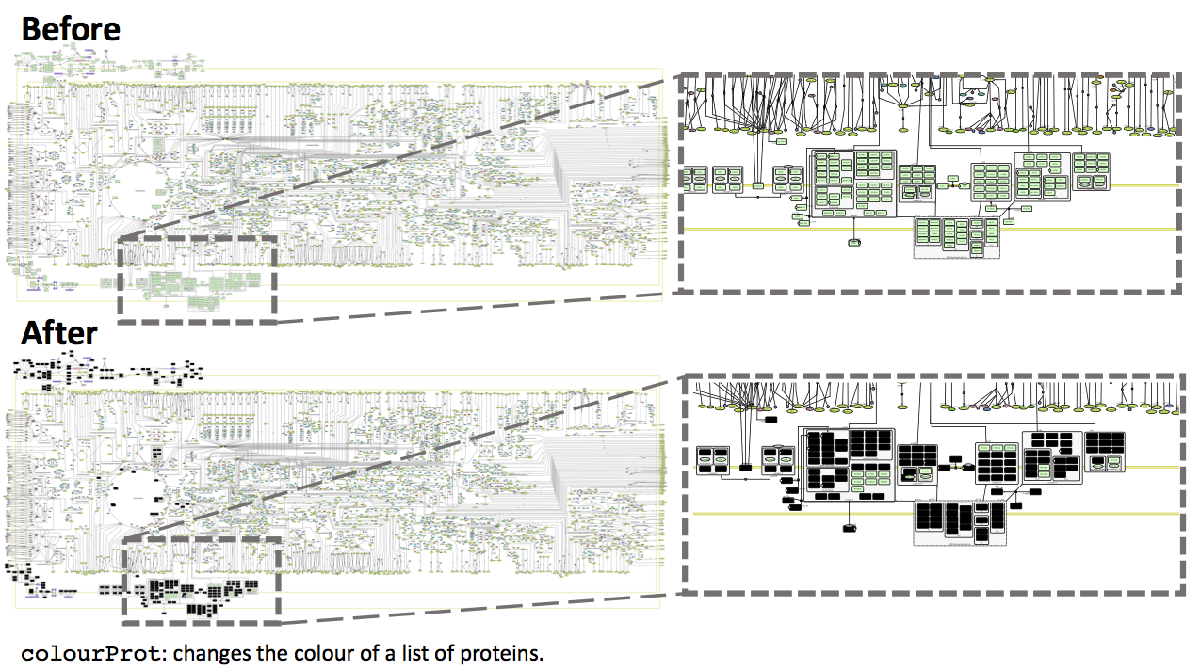

***NOTE!**** A gene can codify for more than one protein. An association protein-gene-metabolicReaction doesn't have to be true. Manual curation would be required in this step.*

## TROUBLESHOOTING

In order to come back to the default map, two functions revert the changes saved in the map. `defaultColorCD` reverts the changes in reactions width and colour (revert all reactions to black and width 1). Furthermore, `defaultColorAndSizeCDMap` reverts to default reactions and nodes (colour and size).

map2 = unifyMetabolicPPImapCD(mapPPI);
transformFullMap2XML(xmlPPI, map2, 'mapPPIUnified.xml');

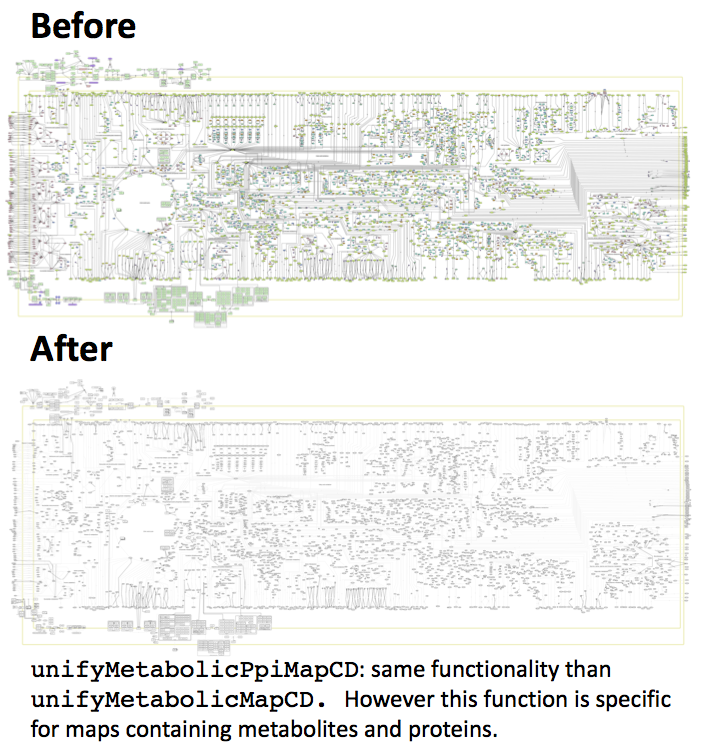

# Specific visualisation for model analysis:

## **Visualise results from Flux Balance analysis (FBA)**

Flux balance analysis is a mathematical approach for analysing the flow of metabolites through a metabolic network. This flow can be added to a parsed XML Matlab structure and visualised a posteriori in CellDesigner.

First, it would be necessary to select an objective function. Since the map represented is a mitochondria (main organelle responsible for energy production in the cell), we would maximize ATP production through complex V in the electron transport chain. 

load('mitomodels.mat')
formulaATPS4m = printRxnFormula(modelMito3D, 'ATPS4m');
model = changeObjective(modelMito3D, 'ATPS4m');
fbaSolution = optimizeCbModel(model, 'max');

The output `FBAsolution` will be afterwards used as input. The width assigned to each reaction in the map is directly related to the flux carried by the reaction in FBA. 

Two types of visualisation are available: 

- For a basic visualisation of fluxes `addFluxFBA` can be used:  

mapGeneralATP = addFluxFBA(mapMitoMetab, modelMito3D, ...
    fbaSolution, 'MEDIUMAQUAMARINE');
transformMap2XML(xmlMitoMetab, mapGeneralATP, 'fbaFlux.xml');

- For a more specific visualisation including directionality of reactions, `addFluxFBAdirectionAndcolour` function can be used:

mapSpecificATP = addFluxFBAdirectionAndColor(mapMitoMetab, ...
    modelMito3D, fbaSolution);
transformMap2XML(xmlMitoMetab, ...
    mapSpecificATP, 'fbaFluxDirectionality.xml');

## Visualize gene expression

A Cytoscape plugin [6] is available to visualize gene expression on top of a network map generated from CellDesigner: **BiNoM** [7].

# Writing information about models to map

Information from the models specific to each reaction or metabolite can be retrieved from the models and added to the CellDesigner map in notes.

mapGlyCorrectedNotes = addNotes(model, mapGlyCorrected);
transformMap2XML(xmlGly, mapGlyCorrectedNotes, 'mapGlyNotes.xml');

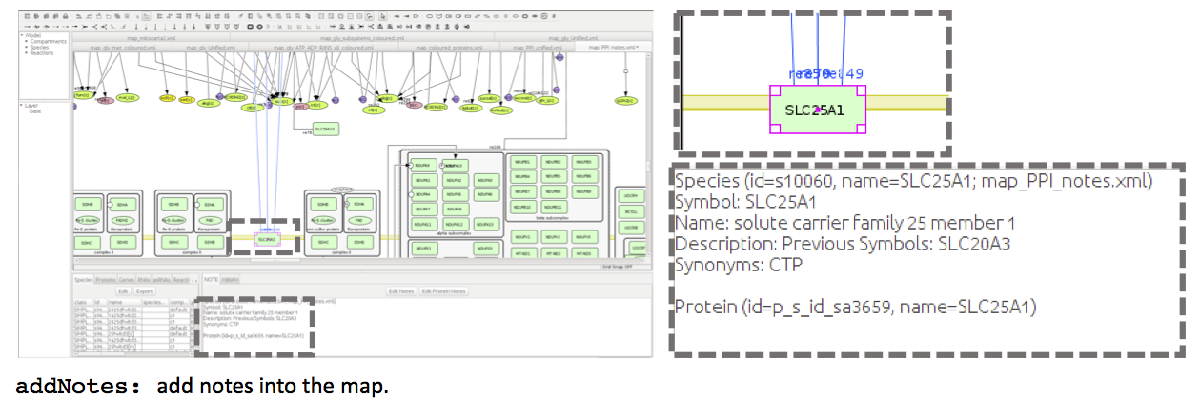

**REFERENCES: **

- Hyduke D. COBRA Toolbox 2.0. *Nature Protocols *(2011). 

- Thiele, I., et al. "A community-driven global reconstruction of human metabolism". *Nat. Biotechnol.,* 31(5), 419-425 (2013).

- Funahashi A.  "CellDesigner: a process diagram editor for gene-regulatory and biochemical networks". *BIOSILICO*, 1:159-162, (2003).

- Kazuhiro A. "Integrating Pathways of Parkinson's Disease in a Molecular Interaction Map". *Mol Neurobiol*. 49(1):88-102 (2014).

- Calvo SE. "MitoCarta2.0: an updated inventory of mammalian mitochondrial proteins". *Nucleic Acids Res*. 4;44(D1):D1251-7 (2016).

- Shannon, Paul et al. “Cytoscape: A Software Environment for Integrated Models of Biomolecular Interaction Networks.” *Genome Research* 13.11 (2003): 2498–2504. *PMC*. Web. 5 Dec. (2017).

- Bonnet E. et al, "BiNoM 2.0, a Cytoscape plugin for accessing and analyzing pathways using standard systems biology formats". *BMC Syst Biol.* 1;7:18 (2013).